%% Load Emotion Dataset (Noisy Version)
data = readtable('emotion_dataset_noisy.csv');


%% Data Cleaning (SFDS Step 1)

% Check for missing values
missing_counts = sum(ismissing(data));
fprintf('Missing values per column:\n');

Missing values per column:


disp(missing_counts);

     0     0     0     0     0     0     0     0     0     0




% Impute missing numeric data with median
numeric_vars = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
for i = 1:width(data)
    if missing_counts(i) > 0 && numeric_vars(i)
        col = data{:,i};
        col(ismissing(col)) = median(col(~ismissing(col)));
        data{:,i} = col;
    end
end

% Handle outliers using IQR-based winsorization
features_raw = data{:, 2:end};
for col = 1:size(features_raw, 2)
    Q1 = quantile(features_raw(:,col), 0.25);
    Q3 = quantile(features_raw(:,col), 0.75);
    IQR = Q3 - Q1;
    lower_bound = Q1 - 1.5 * IQR;
    upper_bound = Q3 + 1.5 * IQR;
    
    features_raw(features_raw(:,col) < lower_bound, col) = lower_bound;
    features_raw(features_raw(:,col) > upper_bound, col) = upper_bound;
end
data{:, 2:end} = features_raw;


%% Exploratory Data Analysis (SFDS Step 2)

% 1. Basic statistics
stats = array2table([mean(features_raw); median(features_raw); std(features_raw)]', ...
    'VariableNames', {'Mean', 'Median', 'StdDev'}, ...
    'RowNames', data.Properties.VariableNames(2:end));
disp('Basic statistics for features:');

Basic statistics for features:


disp(stats);

                          Mean        Median      StdDev 
                       __________    ________    ________

    mouth_width            32.473      32.453      1.4358
    eye_distance           44.476      44.449      1.4526
    eyebrow_raise         0.26811     0.06943     0.32355
    smile_intensity       0.30051    0.034833     0.38082
    frown_intensity       0.32416    0.036961     0.38086
    eye_openness          0.54599     0.53275     0.12925
    mean_GSR                3.902      4.2571      1.1149
    GSR_peaks              3.5319           3      1.7129
    GSR_slope          0.00084208    0.001698    0.098804



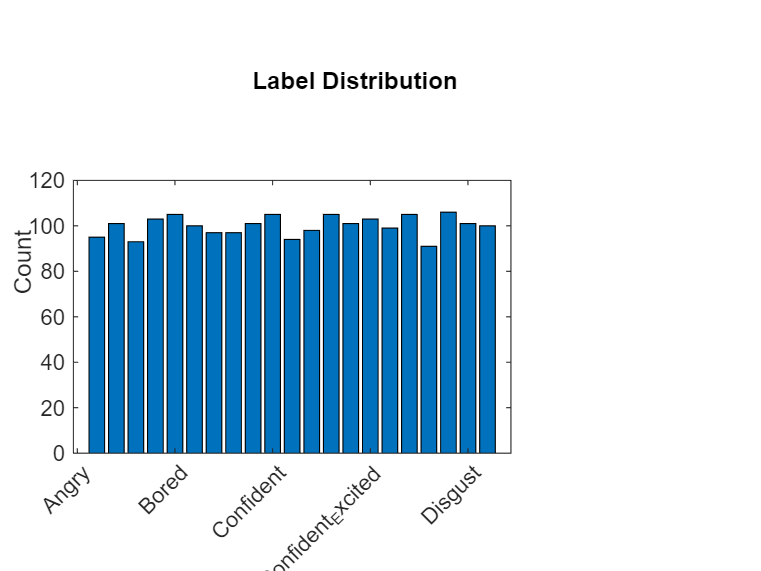


% 2. Label distribution
figure;
label_counts = countcats(categorical(data{:,1}));
bar(label_counts);
xticklabels(categories(categorical(data{:,1})));
xtickangle(45);
ylabel('Count');
title('Label Distribution');

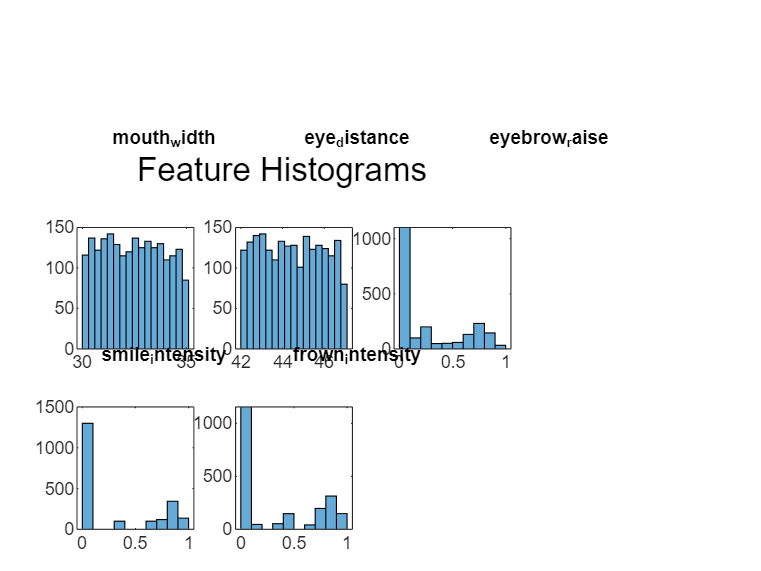


% 3. Feature histograms (first 5 features)
figure;
for i = 1:min(5, size(features_raw,2))
    subplot(2,3,i);
    histogram(features_raw(:,i));
    title(data.Properties.VariableNames{i+1});
end
sgtitle('Feature Histograms');

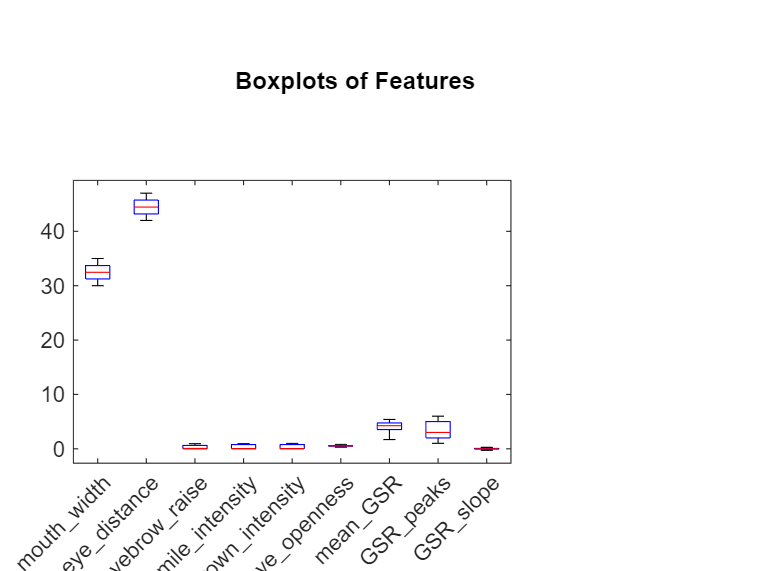


% 4. Boxplots
figure;
boxplot(features_raw, 'Labels', data.Properties.VariableNames(2:end));
xtickangle(45);
title('Boxplots of Features');

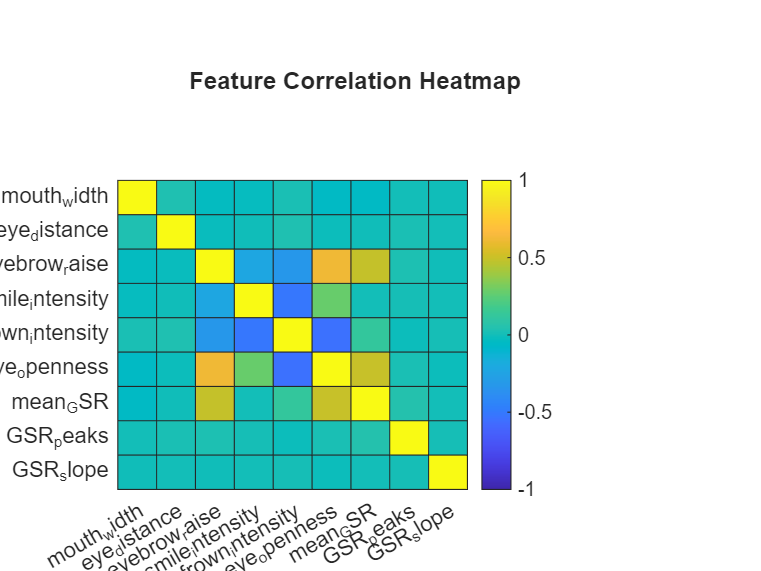


% 5. Correlation heatmap
corr_mat = corr(features_raw);
figure;
heatmap(data.Properties.VariableNames(2:end), data.Properties.VariableNames(2:end), corr_mat, ...
    'Colormap', parula, 'ColorLimits', [-1 1], 'Title', 'Feature Correlation Heatmap');


%% Feature Extraction and Normalization

features = data{:,2:end};
labels = categorical(data{:,1});
features = normalize(features);


%% Train-Test Split

cv = cvpartition(labels, 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

X_train = features(trainIdx, :);
X_test = features(testIdx, :);
y_train = labels(trainIdx);
y_test = labels(testIdx);

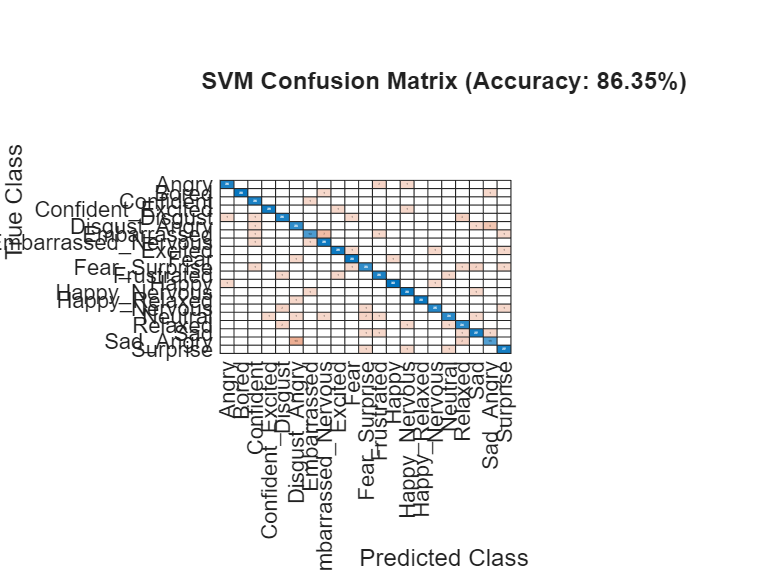


%% SVM Classifier

svm = fitcecoc(X_train, y_train);
pred_svm = predict(svm, X_test);
acc_svm = mean(pred_svm == y_test) * 100;

figure;
confusionchart(y_test, pred_svm);
title(sprintf('SVM Confusion Matrix (Accuracy: %.2f%%)', acc_svm));

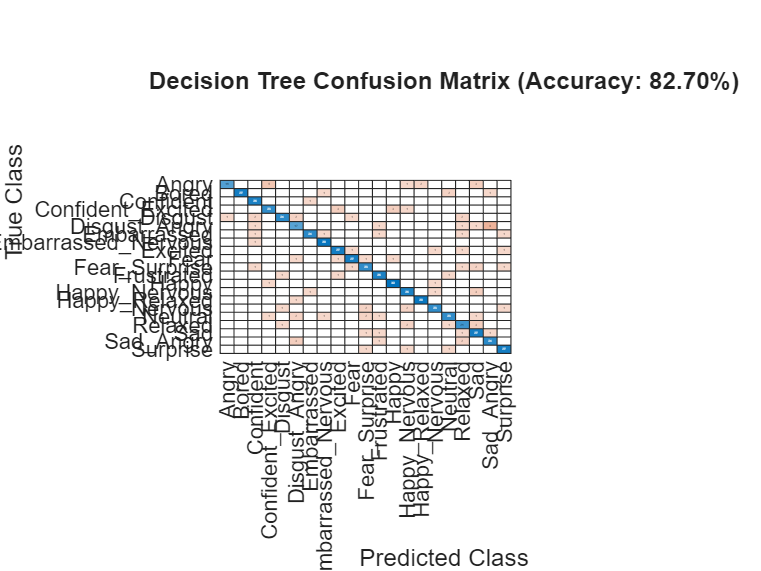


%% Decision Tree Classifier

tree = fitctree(X_train, y_train);
pred_tree = predict(tree, X_test);
acc_tree = mean(pred_tree == y_test) * 100;

figure;
confusionchart(y_test, pred_tree);
title(sprintf('Decision Tree Confusion Matrix (Accuracy: %.2f%%)', acc_tree));

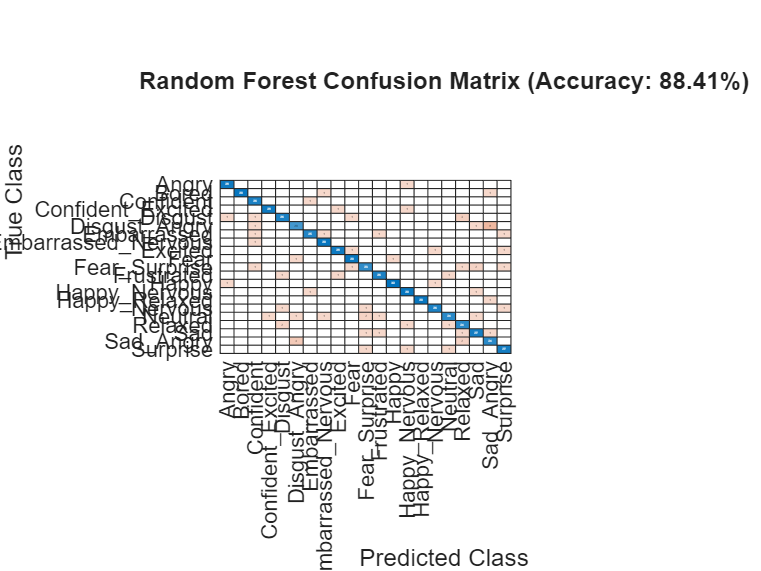


%% Random Forest Classifier

rf = TreeBagger(100, X_train, y_train, 'OOBPrediction', 'On', 'Method', 'classification');
pred_rf = predict(rf, X_test);
pred_rf = categorical(pred_rf); 
acc_rf = mean(pred_rf == y_test) * 100;

figure;
confusionchart(y_test, pred_rf);
title(sprintf('Random Forest Confusion Matrix (Accuracy: %.2f%%)', acc_rf));

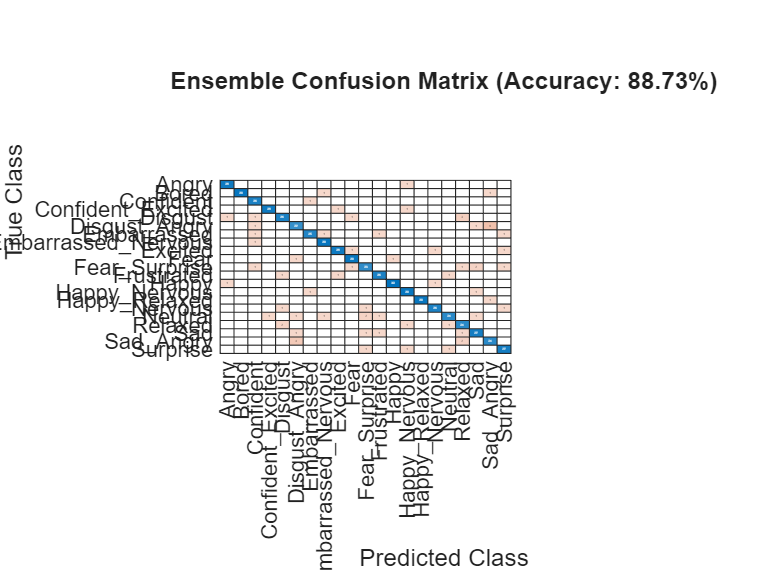


%% Ensemble Classifier

ens = fitcensemble(X_train, y_train, 'Method', 'Bag');
pred_ens = predict(ens, X_test);
acc_ens = mean(pred_ens == y_test) * 100;

figure;
confusionchart(y_test, pred_ens);
title(sprintf('Ensemble Confusion Matrix (Accuracy: %.2f%%)', acc_ens));

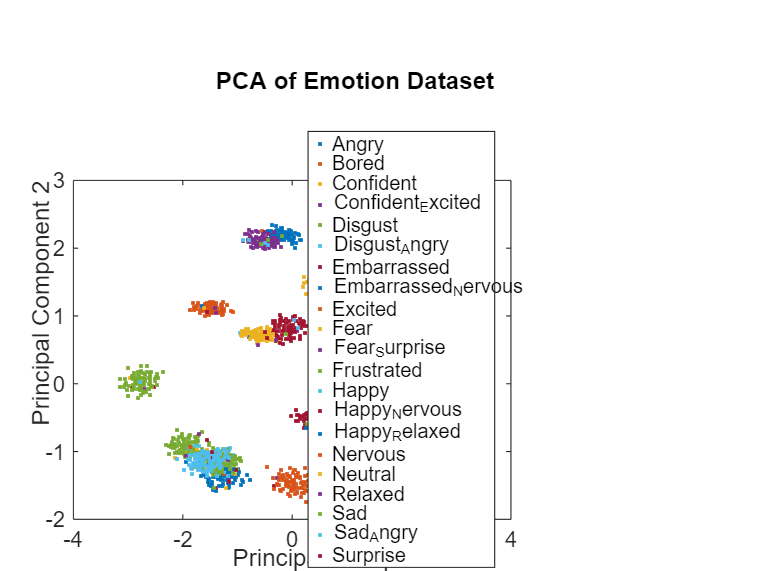


%% PCA Visualization

[coeff, score] = pca(features);
figure;
gscatter(score(:,1), score(:,2), labels);
title('PCA of Emotion Dataset');
xlabel('Principal Component 1');
ylabel('Principal Component 2');

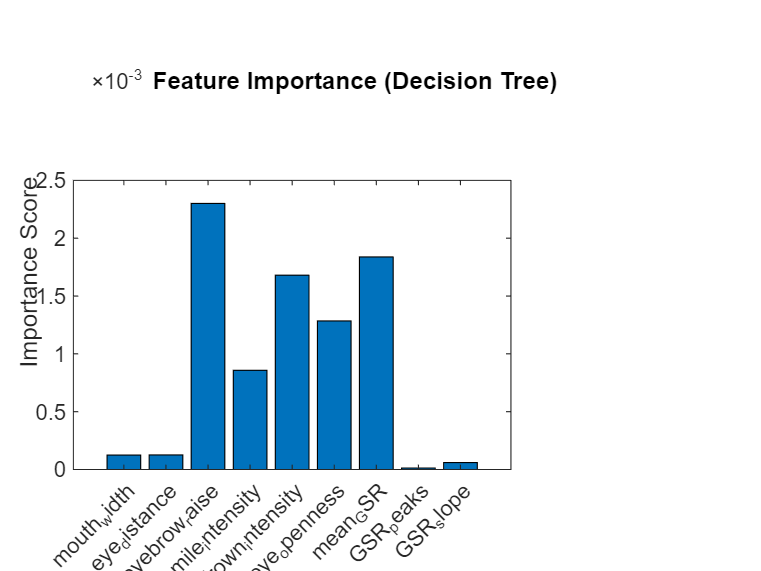


%% Feature Importance (Decision Tree)

figure;
bar(tree.predictorImportance);
xticklabels(data.Properties.VariableNames(2:end));
xtickangle(45);
ylabel('Importance Score');
title('Feature Importance (Decision Tree)');


%% Final Accuracy Report

fprintf('SVM Accuracy: %.2f%%\nDecision Tree Accuracy: %.2f%%\nRandom Forest Accuracy: %.2f%%\nEnsemble Accuracy: %.2f%%\n', ...
    acc_svm, acc_tree, acc_rf, acc_ens);

SVM Accuracy: 86.35%
Decision Tree Accuracy: 82.70%
Random Forest Accuracy: 88.41%
Ensemble Accuracy: 88.73%
